close all;
clear;
clc;

Build a signal

t = 0:1e-5:1e-2-1e-5;
xt = sin(2*pi*1e3*t);
No1 = Radarbox.Type.NoiseType.Gauss;
No2 = Radarbox.Type.NoiseType.Rayleigh;
% No1 = 1;

     2.505936168136362e-01



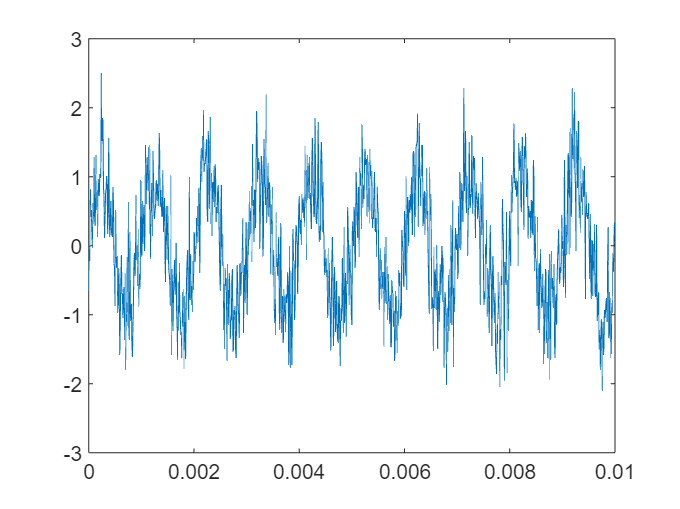

[st,Var] = Radarbox.Noise.Noise_add(xt,No1,3);
disp(Var);plot(t,st);

     1.156822877848658e-02



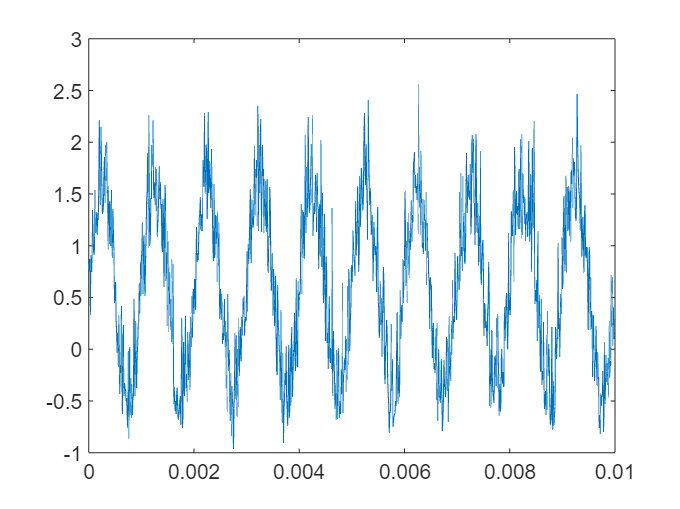

[st,Var] = Radarbox.Noise.Noise_add(xt,No2,3);
disp(Var);plot(t,st);